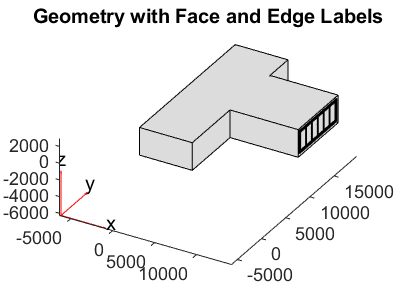

clear;
clc;

% Define constants for signal processing
mapFileName = "D:\ZC\Y5\Spring\Graduation Project\Matlab Code\ZONED.stl";
c = physconst('LightSpeed'); % Speed of light in m/s
fc = 5.8e9; % Carrier frequency in Hz
lambda = c/fc; % Wavelength

% Define antenna array configuration
txArraySize = [4000 1000];
rxArraySize = [4000 4000];
txArray = phased.URA('Size', txArraySize, 'ElementSpacing', 2*lambda); % Use phased.URA for Uniform Rectangular Array
rxArray = phased.URA('Size', rxArraySize, 'ElementSpacing', lambda);

% Import and visualize geometry
figure
gm = importGeometry(mapFileName);
pdegplot(gm);
title('Geometry with Face and Edge Labels');


tx1 = txsite("cartesian", ...
    "Antenna",txArray, ...
    "AntennaPosition",[4200; 15400; 0.1], ...
    'TransmitterFrequency',fc);
tx2 = txsite("cartesian", ...
    "Antenna",txArray, ...
    "AntennaPosition",[4200; 7866; 0.1], ...
    'TransmitterFrequency',fc);
tx3 = txsite("cartesian", ...
    "Antenna",txArray, ...
    "AntennaPosition",[13900; 7866; 0.1], ...
    'TransmitterFrequency',fc);
tx4 = txsite("cartesian", ...
    "Antenna",txArray, ...
    "AntennaPosition",[13900; 15400; 0.1], ...
    'TransmitterFrequency',fc);

% Define office dimensions
officeDimensions.xMin = 4200;   % Minimum x-coordinate
officeDimensions.xMax =13900;  % Maximum x-coordinate
officeDimensions.yMin = 7866;   % Minimum y-coordinate
officeDimensions.yMax = 15400;   % Maximum y-coordinate
officeDimensions.zMin = 0.1;   % Minimum z-coordinate
officeDimensions.zMax = 1000;   % Maximum z-coordinate
rxs = generateRandomReceivers(150, rxArray, officeDimensions);
txs = [tx1, tx2, tx3, tx4];

% Visualize the map and sites
siteviewer("SceneModel", mapFileName, "Transparency", 0.25);
show(txs, "ShowAntennaHeight", false);
show(rxs, "ShowAntennaHeight", false);

% Define propagation model
pm = propagationModel("raytracing", ...
    "CoordinateSystem", "cartesian", ...
    "Method", "sbr", ...
    "SurfaceMaterial", "wood", ...
    "MaxNumReflections", 2);

% Perform ray tracing
rays = raytrace(txs, rxs, pm);

current_rays = [];
for tx_index = 1:length(txs)
    for rx_index = 1:length(rxs)
        current_rays = [current_rays, rays{tx_index,rx_index}];
    end
end


figure;
plot(current_rays, "Colormap", jet, "ColorLimits", [50, 150]);

Error using matlabshared.threejs.CartesianController/waitForResponse
Timed out

Error in matlabshared.threejs.CartesianController/request

Error in matlabshared.threejs.CartesianViewer/submitPlots

Error in comm.Ray/plot (line 973)
    viewer.Visualizer.submitPlots('Animation', submitAnim);


rssiFeatures = extractRSSI_Features(rays);


% Calculate CIR features

CIR_features = extractCIR_Features(rays);


% Combine CIR and RSSI features
combinedFeatures = [CIR_features rssiFeatures];

% Normalize combined features
%combinedFeatures = normalize(combinedFeatures, 'range');

% Generate labels
labels = generateLabels(rxs);

simulated_dataset = [combinedFeatures labels];

% Convert tables to struct for JSON encoding
simulatedDatasetStruct = table2struct(simulated_dataset);

% Convert struct to JSON
jsonSimulatedDataset = jsonencode(simulatedDatasetStruct);

% Define the Flask server URL for simulated data
url_simulated_data = 'http://10.20.141.37:5000/simulated_data';

% Set options for the webwrite function
options = weboptions('MediaType', 'application/json');

% Send the JSON data to the Flask server
response_simulated_data = webwrite(url_simulated_data, jsonSimulatedDataset, options);

% Display the response from the server
disp(response_simulated_data);

% Function to convert the combinedFeatures table to a struct array

function structArray = table2struct(table)
    structArray = struct([]);
    for i = 1:height(table)
        structArray(i).meanToA_TX_1 = table.meanToA_TX_1(i);
        structArray(i).stdToA_TX_1 = table.stdToA_TX_1(i);
        structArray(i).maxAmplitude_TX_1 = table.maxAmplitude_TX_1(i);
        structArray(i).meanAmplitude_TX_1 = table.meanAmplitude_TX_1(i);
        structArray(i).stdAmplitude_TX_1 = table.stdAmplitude_TX_1(i);
        structArray(i).meanToA_TX_2 = table.meanToA_TX_2(i);
        structArray(i).stdToA_TX_2 = table.stdToA_TX_2(i);
        structArray(i).maxAmplitude_TX_2 = table.maxAmplitude_TX_2(i);
        structArray(i).meanAmplitude_TX_2 = table.meanAmplitude_TX_2(i);
        structArray(i).stdAmplitude_TX_2 = table.stdAmplitude_TX_2(i);
        structArray(i).meanToA_TX_3 = table.meanToA_TX_3(i);
        structArray(i).stdToA_TX_3 = table.stdToA_TX_3(i);
        structArray(i).maxAmplitude_TX_3 = table.maxAmplitude_TX_3(i);
        structArray(i).meanAmplitude_TX_3 = table.meanAmplitude_TX_3(i);
        structArray(i).stdAmplitude_TX_3 = table.stdAmplitude_TX_3(i);
        structArray(i).meanToA_TX_4 = table.meanToA_TX_4(i);
        structArray(i).stdToA_TX_4 = table.stdToA_TX_4(i);
        structArray(i).maxAmplitude_TX_4 = table.maxAmplitude_TX_4(i);
        structArray(i).meanAmplitude_TX_4 = table.meanAmplitude_TX_4(i);
        structArray(i).stdAmplitude_TX_4 = table.stdAmplitude_TX_4(i);
        structArray(i).RSSI_TX_1 = table.RSSI_TX_1(i);
        structArray(i).RSSI_TX_2 = table.RSSI_TX_2(i);
        structArray(i).RSSI_TX_3 = table.RSSI_TX_3(i);
        structArray(i).RSSI_TX_4 = table.RSSI_TX_4(i);
        structArray(i).x = table.x(i);
        structArray(i).y = table.y(i);
        structArray(i).z = table.z(i);
    end
end

function labels = generateLabels(rxs)
    % Initialize labels matrix
    numReceivers = length(rxs);
    labelNames = {'x', 'y', 'z'};
    labels = array2table(zeros(numReceivers, length(labelNames)), 'VariableNames', labelNames);
    % Iterate over each receiver
    for i = 1:numReceivers
        % Directly store coordinates
        labels{i, :} = [rxs(i).AntennaPosition(1), rxs(i).AntennaPosition(2), rxs(i).AntennaPosition(3)];
    end
end

function rxs = generateRandomReceivers(n, rxArray, officeDimensions)
    % n is the number of receivers to generate
    % officeDimensions is a struct with fields xMin, xMax, yMin, yMax, zMin, zMax
    % defining the boundaries of the office space
    
    % Initialize the array of receiver structures
    rxs = repmat(rxsite(), 1, n);
    
    % Generate n receivers with random positions within the office
    for i = 1:n
        % Randomly generate X, Y, Z coordinates within the office boundaries
        x = officeDimensions.xMin + (officeDimensions.xMax - officeDimensions.xMin) * rand();
        y = officeDimensions.yMin + (officeDimensions.yMax - officeDimensions.yMin) * rand();
        z = officeDimensions.zMax;
        
        % Assign the generated position and a default antenna angle to the receiver
        rxs(i) = rxsite("cartesian", ...
            "Antenna",rxArray, ...
            "AntennaPosition",[x; y; z], ...
            "AntennaAngle",[0;90]);
    end
end

function CIR_features = extractCIR_Features(rays)
fc = 5.8e9; % Carrier frequency in Hz

    baseFeatureNames = {'meanToA', 'stdToA', 'maxAmplitude', 'meanAmplitude', 'stdAmplitude'};
    featureNames = {};
    % Loop over each transmitter and append the TX number to each feature name
    for tx = 1:size(rays,1)
        for i = 1:length(baseFeatureNames)
            featureNames{end+1} = [baseFeatureNames{i} '_TX_' num2str(tx)];
        end
    end
    % Convert the cell array to a table with zero rows initially
    CIR_features = array2table(zeros(size(rays,2), length(featureNames)), 'VariableNames', featureNames);
     
    for tx_index = 1:size(rays,1)
        for rx_index = 1:size(rays,2)
            current_rays = rays{tx_index, rx_index}; % Get rays for the current TX-RX pair
            ToAs = []; % Times of Arrival
            Amplitudes = []; % Complex amplitudes
            
            for ray_index = 1:length(current_rays)
                ray = current_rays(ray_index);
                ToA = ray.PropagationDelay;
                ToAs = [ToAs, ToA];
                amplitude = 1 / sqrt(ray.PathLoss); % Ensure PathLoss is in linear scale
                phase_shift = 2 * pi * fc * ToA; % Phase shift calculation
                complex_amplitude = amplitude * exp(1i * phase_shift);
                Amplitudes = [Amplitudes, complex_amplitude];
            end
            
            meanToA = mean(ToAs);
            stdToA = std(ToAs);
            maxAmplitude = max(abs(Amplitudes));
            meanAmplitude = mean(abs(Amplitudes));
            stdAmplitude = std(abs(Amplitudes));
    
            tx_index_cir = (5 * (tx_index - 1)) + 1;
            CIR_features{rx_index, tx_index_cir} = meanToA;
            CIR_features{rx_index, tx_index_cir + 1} = stdToA;
            CIR_features{rx_index, tx_index_cir + 2} = maxAmplitude;
            CIR_features{rx_index, tx_index_cir + 3} = meanAmplitude;
            CIR_features{rx_index, tx_index_cir + 4} = stdAmplitude;
        end
    end
end


function rssiFeatures = extractRSSI_Features(rays)
    txPower = 20; % Increased transmitter power in dBm
    txGain = 5; % Increased transmitter antenna gain in dBi
    rxGain = 5; % Increased receiver antenna gain in dBi
    % Calculate RSSI features
    rssi = zeros(size(rays,2), size(rays,1)); % Initialize RSSI matrix
    for tx_index = 1:size(rays,1)
        for rx_index = 1:size(rays,2)
            current_rays = rays{tx_index, rx_index}; % Get rays for the current TX-RX pair
            % Calculate RSSI
            pathLoss = calculatePathLoss(current_rays); % Calculate path loss
            rssi(rx_index, tx_index) = txPower + txGain + rxGain - pathLoss; % RSSI calculation
        end
    end
    txs_names = {'RSSI_TX_1', 'RSSI_TX_2', 'RSSI_TX_3', 'RSSI_TX_4'};
    rssiFeatures = array2table(rssi, 'VariableNames', txs_names);
end

function pathLoss = calculatePathLoss(rays)
    pathLossLinearSum = 0;
    for i = 1:length(rays)
        pathLossLinear = 10^(-rays(i).PathLoss / 10); % Convert dB to linear scale
        pathLossLinearSum = pathLossLinearSum + pathLossLinear;
    end
    pathLoss = -10 * log10(pathLossLinearSum); % Convert back to dB
end